## **Step 1: Create a PD model for Target Pharmacology Assessment (TPA). **

Here a simple indirect response model is provided as an example. Below is overview diagram of the model and the set of model equations.

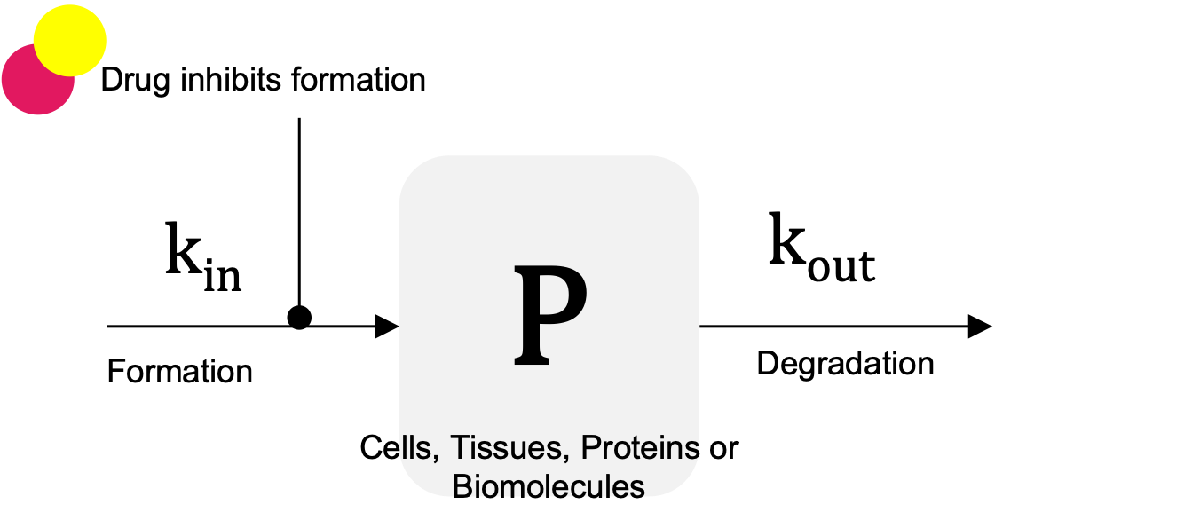

## 
$$\begin{array}{l}
\frac{\textrm{dP}}{\textrm{dt}}=k_{\textrm{in}} D_{\textrm{effect}} -k_{\textrm{out}} P\;\;\;\;\;\;\;\;\;\;P\left(t=0\right)=1\\
D_{\textrm{effect}} =1-I_{\max } \textrm{TE}\\
\textrm{TE}=\frac{f_u C}{f_u C+{\textrm{IC}}_{50} }
\end{array}$$
               

**Note: The user is allowed to create the PD model as they wish with very minimal requirements for integrating with PK/PBPK model for performing TPA. **

**Requirements:**

- The PD model must contain a species named "TE."  This species is used to modulate the target when simulating the intensity and duration of "target knockdown."  for mode 1 analysis. Its also used to couple the PK / PBPK model with PD. The initial amount of this should be zero (no drug means no target knockdown). You will also need to add a dummy variable called "one_TE" for unit conervsions (target engagement is technically dimensionless but because Simbiology does not like species without units, we need to define a unit for TE and divide by one unit to make it dimensionless). **The parameter name must be "one_TE"**

- Add parameter "cl_TE" which is a clearance term for species pd.TE. **The parameter must be named cl_TE with units 1/hour. The reaction "Name" must be "TE clearance for TE simulations." **This reaction is used with infusion dosing (described below) to modulate target knockdown. The name of this reaction is critical because it is removed when merging with the PBPK model (removing the reaction ensures there is no inadvertant modulation of the target when running with the PBPK model).

-  Add the dose for pd.TE to run target knockdown simulations for mode 1 analysis. **The dose name must be te_dose with "Target" field of the dose set to the TE species**

Below is the example code where we generate a simple indirect response model.

mPD = createIndirectResponseModel();
mPD.getequations

ans =     'ODEs:
     d(TE)/dt = -[TE clearance for TE Simulations]
     d(P)/dt = 1/pd*(-R_degradation_P + R_synthesis_P)
     
     Fluxes:
     [TE clearance for TE Simulations] = TE*cl_TE
     R_degradation_P = (kout*P)*pd
     R_synthesis_P = (kin*drugEffect)*pd
     
     Repeated Assignments:
     Pinhb = 100*(P0-P)/P0
     drugEffect = 1-Imax*TE/one_TE
     
     Parameter Values:
     one_TE = 1 molecule
     Imax = 1 dimensionless
     cl_TE = 0 1/hour
     kin = 1 nanomole/(liter * hour)
     kout = 1 1/hour
     P0 = 1 nanomole/liter
     pd = 1 liter
     drugEffect = 1 dimensionless
     Pinhb = 0 dimensionless
     
     Initial Conditions:
     TE = 0 molecule
     P = 1 nanomole/liter
     
     '


mexpPD = export(mPD); 

## STEP 2: Perform target engagement vs duration scan                        (Mode 1 Analysis)

Use the runTargetEngagementScan.m script in the toolbox to perform the mode 1 analysis. 

**Requirements:**

Defined by the runTargetEngagementScan.m script. See below example for details and the runTargetEngagementScan.m documentation.  One of the requirements is a **csv file with parameters of the PD model defined in it**.

**Notes: **

- The scripts could be easily parallelized by replacing the for loop with parfor to run scans for different amplitude and duration.

- Currently the script wont allow to test a single run at a fixed amplitude and duration and wont allow to easily debug the entire profile since it saves the endpoint calculated from the profile for generating contour plot. (For ease for the users I have added a file called runSingleAmplitudeDurationExperiment.m for help with debugging. To be consistent with the current scripts I allow only exported models but we could support nonexported model in future following the same idea)

- Current script only allows to work with exported model. Could be modified  to allow nonexported model for debugging purposes but requires some changes to the code

- Potential error on line 211 of runTargetEngagementScan.m ... needs to be checked

#### Step 2a: Single target engagement and duration combination for testing and debugging

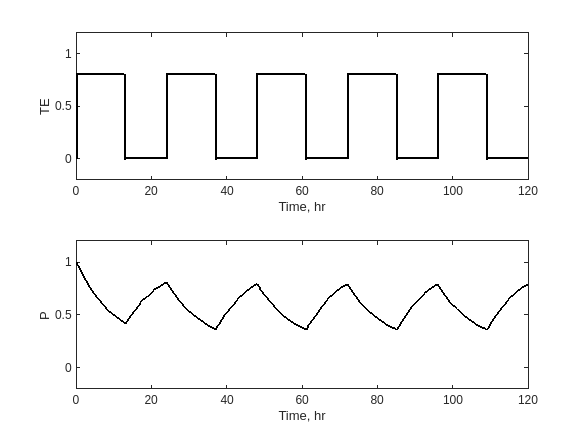

duration =13;
teAmount = 0.8;
stopTimeDays = 5;
pdParamFileName='indirectResponsePDparameters.csv';
plotVariables = {'pd.TE', 'pd.P'};
ylimit = {[-0.2, 1.2], [-0.2, 1.2]};
sdata= runSingleAmplitudeDurationExperiment(mexpPD, ...
    teAmount,duration,stopTimeDays,pdParamFileName, ...
    plotVariables, ylimit);

#### Step 2b: Running mode 1 analysis

meshPoints = 10, will run 100 simulations.



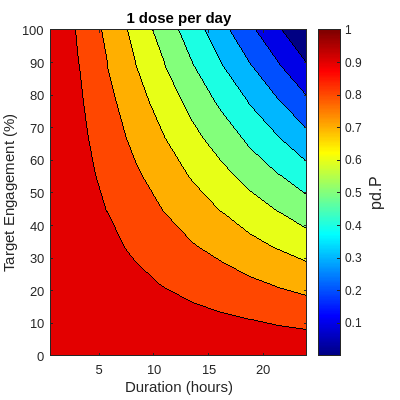

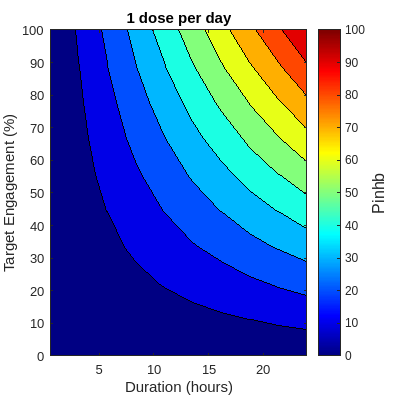

% Define the section below according to your own PD model
% --------------------------------------------------------
dosesPerDay = 1; stopTimeDays = 30;
speciesToPlot = {'pd.P', 'Pinhb'}; 
aggregationType = 'min'; aggregationDuration = 'lastdose';
outputFilename = 'indirectResponseTargetScan.mat';
meshPoints = 10; numberOfContours = 10;
variantContent = buildPDVariantContent('indirectResponsePDparameters.csv');
% ---------------------------------------------------------

res = runTargetEngagementScan( ...
    mexpPD, variantContent, ...
    dosesPerDay, stopTimeDays, ...
    speciesToPlot, ...
    aggregationType, aggregationDuration, outputFilename, ...
    meshPoints, numberOfContours);

## STEP 3: Leverage the PBPK template in toolbox to generate the PBPK model structure and expand it if needed.

You can use unbound plasma concentration or the unbound drug concentration in the target tissue of interest to drive the PD model. While integrating the PBPK with PD model as shown in the next step use the appropriate species name from the PBPK model that drives the PD according to program need.

mPK = createPBPKmodel();
clearvars -except mPK mPD;

## STEP 4: Integrate the PBPK model with the PD model.

**Requirements:**

    1. Remove the cl_TE reaction added for mode 1 analysis. This is not required for the mode 2 analysis

    2. Add potency  parameter and a rule for TE which uses the species from the PBPK model to drive the PD model. 

**Note this simlification of PBPK and PD interaction using the TE rule is only valid for small molecule where we assume reversible interaction with target of interest. Other MOAs might require the interaction to be done differently. **

Two options to perform the merge.

    1. Use the mergePDAndPBPK.m function in the toolbox to perform the merge following instructions in SMARCA2-TPA. Link : [https://mygithub.gsk.com/gsk-tech/smarca2-tpa/](https://mygithub.gsk.com/gsk-tech/smarca2-tpa/) which requires defining parameters, species, rules and reactions for the merge in a excel file

    2. Follow the example below to perform merge using a script with definition for the interaction and mrgMod.m function in toolbox to perform the merge

mPKPD = integratePDandPBPK(mPD, mPK);
mPKPDexp = export(mPKPD); accelerate(mPKPDexp);

## STEP 5: Generate a set of virtual compound varying different ADME properties.

**Requirements:**

-  A excel file with the list of parameters to varied with their ranges and information. The parameters and ranges for the properties are from the TRPM2 and earlier TPAs, however they need to be looked over once again.


$$$\left\lbrack \begin{array}{ccccccccc}
 &\bf{ParameterName} &  \bf{Distribution} &  \bf{Val} &  \bf{Min}&  \bf{Max} & \bf{Mean} & \bf{StdDev} & \bf{Units}\\
 1 & solubility&  log-uniform&  NULL&  0.01&  5&  NULL&  NULL & mg/mL\\
 2 & solubility-pH & constant & -1  & NULL  & NULL  &NULL  &NULL & \\
 3 & SF & constant & 20  & NULL  & NULL & NULL &NULL  &  \\
 4  &logP & uniform &  & NULL 0  & 5  & NULL & NULL  & dimensionless \\
 5 &Papp  &log-uniform  & NULL  &1  &1000  & NULL  & NULL  & cm/s \\
 6 & Deff  & uniform & NULL  & 1e-6  & 2e-5  & NULL  & NULL  & cm^2/s \\
 7 & BP & uniform & NULL  & 0.7  & 4  & NULL  & NULL  & dimensionless \\
 8 & fup & log-uniform & NULL  & 0.0 & 0.7  & NULL & NULL & dimensionless\\
 9 & CLint_u & log-uniform  & NULL  &  1  & 300  & NULL  & NULL  & mL/ min / g (liver weight) \\
 10 & mw & uniform & NULL  & 190  & 900  & NULL  & NULL   & dalton\\
 11 & pRC50 & log-uniform & NULL  & 6  & 12 & NULL & NULL  & M\\
\end{array}\right\rbrack$$$


% Generate a large number of virtual compounds for mode 2 analysis
N = 10000; vcmpds = buildVirtualCompounds('tpaParameters.xlsx', N);
vcmpds.Peff = convert_Papp_to_Peff(vcmpds.Papp,'method1');
vcmpds.RC50 = 10.^(-vcmpds.pRC50).* vcmpds.mw.*1e6; % assuming RC50 is in units of ng/mL - pR50 is -log10(RC50 [M])

% Getting values of a single compound (just for debugging)
vcmpd = getInfoSingleVirtualCompound(vcmpds, 6)

vcmpd = struct with fields:
       Ncompounds: 10000
            cpdId: {'6'}
       solubility: 0.0580
    solubility_pH: -1
               SF: 20
             logP: 4.4603
             Papp: 969.2625
             Deff: 6.2224e-06
               BP: 3.9617
              fup: 0.0823
          CLint_u: 263.0294
               mw: 636.5056
            pRC50: 7.9289
            pKa_a: NaN
            pKa_b: 9.3570
             Peff: 6.5939
             RC50: 7.4971


## STEP 6: Examine PD response upon probing the PBPK-PD model with the generated virtual compounds

**Requirements:**

-  A excel file with the additional TPA protocol information such as the type of fut_method, number of total doses etc. Please see the tpaProtocol.xlsx 

Notes:

        1. The current code does not allow to look at individual traces and since its running simulations in parallel wont allow debugging without changing the parfor loop to a for loop either.

#### STEP 6a. Evaluate a single virtual compound before running large scale simulations. 

I have added some temporary scripts until toolbox update to run simulation for single virtual compound examine the profiles of drug and PD response of interest. It will assist in checking the invidiual traces for understanding and debugging purposes. runSingleCmpdPBPKandPD.m and runSingleCmpd.sim which are copies of runVirtualScreen.m and runVirtualSimulation.m functions in the toolbox with minor modification are added here in the folder. Future update to the toolbox files will make this files not useful.

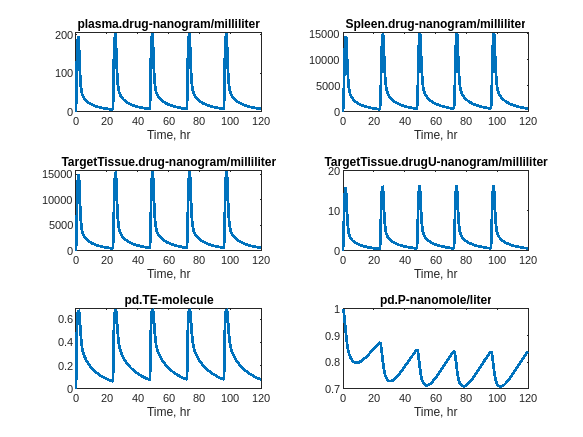

pdVariantContent = buildPDVariantContent('indirectResponsePDparameters.csv');
protocol = readcell('tpaProtocol.xlsx');
protocolTable = cell2table(protocol(2:end,:),'VariableNames',protocol(1,:));

[virtCpdsStructArray1, results1, simData1, doseAmounts1, failedRunsStruct1] = ...
    runSingleCmpdPBPKandPD( mPKPDexp, pdVariantContent, vcmpd, ...
    protocolTable, '', {'plasma.drug','Spleen.drug', 'TargetTissue.drug', ...
    'TargetTissue.drugU', 'pd.TE', 'pd.P'});

Extract derived properties for the compound such as fut, Kpavg, Vss etc. Look in the runSingleCmpdPBPKandPD.m lines 551-564 for fut and Kpavg calculation. Currently this two derived properties not extracted in the runVirtualScreen.m

virtCpdsStructArray1

virtCpdsStructArray1 = struct with fields:
               vc_id: '6'
                  mw: 636.5056
          solubility: 0.0580
                  SF: 20
                  SR: 0
                logP: 4.4603
           logD_pH74: 2.5316
                Peff: 6.5939
                Deff: 6.2224e-06
                  BP: 3.9617
                 fup: 0.0823
                 fub: 0.0208
             CLint_u: 263.0294
       CL_bl_mLminkg: 15.8675
       CL_pl_mLminkg: 62.8626
    CLren_pl_mLminkg: 0
           CL_pctLBF: 88.1527
          Vss_pl_Lkg: 32.5088
          Vss_bl_Lkg: 8.2057
        Thalf_clv_hr: 5.9742
          acidic_pKa: NaN
           basic_pKa: 9.3570
                Papp: 969.2625
               pRC50: 7.9289
                RC50: 7.4971
               Kpavg: 37.9835
             KpTable: [13×11 table]
         fut_method1: 0.0022
         fut_method2: 0.0022


#### STEP 6b. Large scale simulations to evaluate thousdands of virtual compounds 

clearvars -except mPKPD mPKPDexp pdVariantContent vcmpds protocolTable
[virtCpdsStructArray, results, doseAmounts, failedRunsStruct] = ...
    runVirtualScreen(...
    mPKPDexp, pdVariantContent, vcmpds, ...
    protocolTable, '');

## STEP 7: Analysis of the results

#### Step 7a. Extract and plot the PD response of interest against cmin, cmax etc to indentify the best PK driver visually.

% Extracting the the quantities of interest from the results for a fixed
% dose here. Just an example. You might extract additional outputs as
% needed 
doseno = 7; totaldoses = length(doseAmounts);
response = [results.pd_P]; response = response(doseno:totaldoses:end);
cmin = abs([results.UnboundClast_ngmL]); cmin = cmin(doseno:totaldoses:end);
cmax = abs([results.UnboundCmax_ngmL]); cmax = cmax(doseno:totaldoses:end);
cavg = abs([results.UnboundCss_ngmL]); cavg = cavg(doseno:totaldoses:end);
tRC50 = [results.t_RC50]; tRC50 = tRC50(doseno:totaldoses:end);
rc50 = [virtCpdsStructArray.RC50];
sol = [virtCpdsStructArray.solubility];
per = [virtCpdsStructArray.Peff];

Create visualization of Cmin/RC50 vs Cavg/RC50 as example to identify PK driver

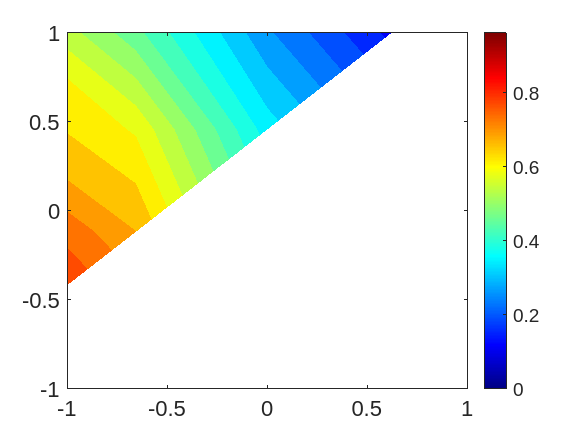

% If any of cmin, cavg or response value is nan the contour plot wont work 
% You will have to preprocess the data first. This could be done
% automatically through additional functions / script but currently not
% supported. 
contourfUnstructured(log10(cmin./rc50), ...
    log10(cavg./rc50), response); xlim([-1, 1]); ylim([-1, 1])

Alternate visualization of the above plot

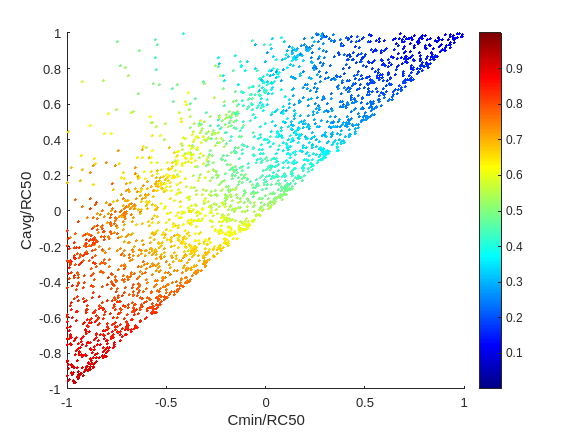

figure; scatter(log10(cmin./rc50), log10(cavg./rc50), 5,response, 'filled','o');
colormap("jet"); xlim([-1,1]); ylim([-1, 1]);
xlabel('Cmin/RC50'); ylabel('Cavg/RC50'); colorbar();

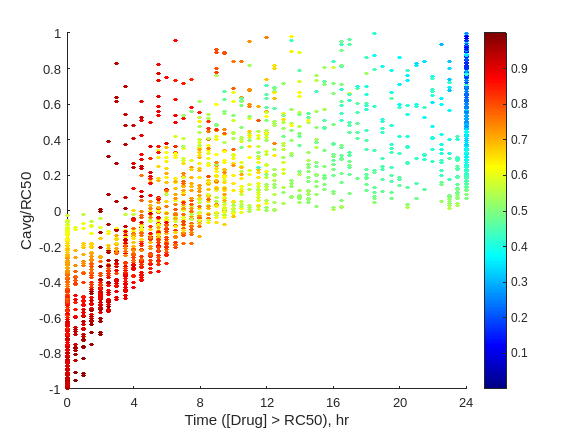

figure; scatter(tRC50, log10(cavg./rc50), 10,response, 'filled','o');
colormap("jet"); xlim([0,24]); ylim([-1, 1]); xticks(0:4:24)
xlabel('Time ([Drug] > RC50), hr'); ylabel('Cavg/RC50'); colorbar();

#### STEP 7b: Calculate Minimum effective dose (MED) for each virtual compound that results at the PD response level

Example script to calculate the MED based on earlier TPAs (not most general). A improved function to calculate the MED might be added later to the toolbox .

warning('off')
res_med = calculateMED(virtCpdsStructArray, results, doseAmounts,...
    {'pd_TE', 'pd_P','UnboundAUCinf_nghrmL',...
     'UnboundAUCt_nghrmL','UnboundCss_ngmL','UnboundClast_ngmL',...
     'UnboundCmax_ngmL', 't_RC50_drug'},'pd_P', 0.5, '<')

res_med = 10000×35 table
    vc_id       mw      solubility    SF    SR     logP      logD_pH74     Peff         Deff         BP          fup          fub        CLint_u    CL_bl_mLminkg    CL_pl_mLminkg    CLren_pl_mLminkg    CL_pctLBF    Vss_pl_Lkg    Vss_bl_Lkg    Thalf_clv_hr    acidic_pKa    basic_pKa     Papp     pRC50       RC50       MED_mod    MED_mg     pd_TE        pd_P      UnboundAUCinf_nghrmL    UnboundAUCt_nghrmL    UnboundCss_ngmL    <s

warning('on')

#### STEP 7C: Contour plot of probability of success with respect to ADME properties

Example script to estimate and plot POS based on earlier TPAs (not most general). A improved function to estimate POS and generate plot might be added to the toolbox.

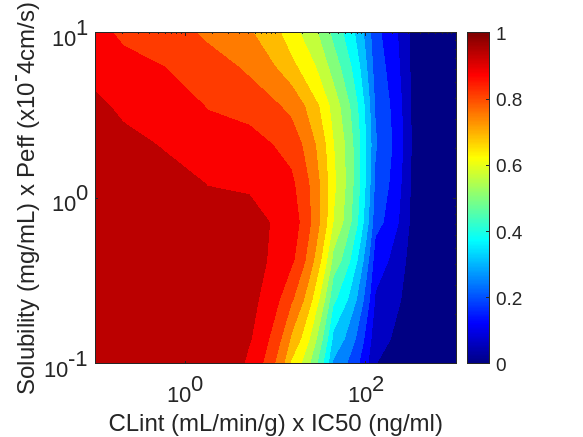

f =contourPlotPOS(res_med, [10^-1, 10^3], [10^-1, 10^1]);

#### STEP 7D: Decision tree to identify the key ADME properties

featuresTb = array2table([log(vcmpds.RC50), log(vcmpds.CLint_u), ...
    log(vcmpds.solubility), log(vcmpds.Peff)], ...
    'VariableNames', {'RC50','CLint', 'sol','Peff'});
responseTb = array2table(response', 'VariableNames', {'Target'});
mdl = fitrtree(featuresTb, responseTb, 'maxNumSplits', 3);
% view(mdl, graph); % comment out this line if you want to see a graph view
% of the decision tre
view(mdl); 

Decision tree for regression
1  if RC50<0.846207 then node 2 elseif RC50>=0.846207 then node 3 else 0.45176
2  if RC50<-2.11284 then node 4 elseif RC50>=-2.11284 then node 5 else 0.151249
3  if CLint<2.53718 then node 6 elseif CLint>=2.53718 then node 7 else 0.774975
4  fit = 0.0519249
5  fit = 0.302508
6  fit = 0.622753
7  fit = 0.895395



#### STEP 7E: Decision tree to identify the primary PK driver

featuresTb = array2table([log(cmin./rc50); log(cmax./rc50); ...
    log(cavg./rc50); tRC50]', ...
    'VariableNames', {'Cmin', 'Cmax', 'Cavg', 'tRC50'});
idx = find(featuresTb.Cmin > -1 & featuresTb.Cmin < 1 & ...
    featuresTb.Cmax < 1 & featuresTb.Cmax > -1);
responseTb = array2table(response', 'VariableNames', {'Target'});
mdl = fitrtree(featuresTb(idx, :), responseTb(idx, :), 'maxNumSplits', 3);
% view(mdl, graph); % comment out this line if you want to see a graph view
% of the decision tre
view(mdl); 

Decision tree for regression
1  if tRC50<11.75 then node 2 elseif tRC50>=11.75 then node 3 else 0.552631
2  if Cavg<-0.318593 then node 4 elseif Cavg>=-0.318593 then node 5 else 0.635899
3  if Cavg<0.445329 then node 6 elseif Cavg>=0.445329 then node 7 else 0.454749
4  fit = 0.68592
5  fit = 0.590515
6  fit = 0.495625
7  fit = 0.393437

